# Chapter 6 - Exercises

## 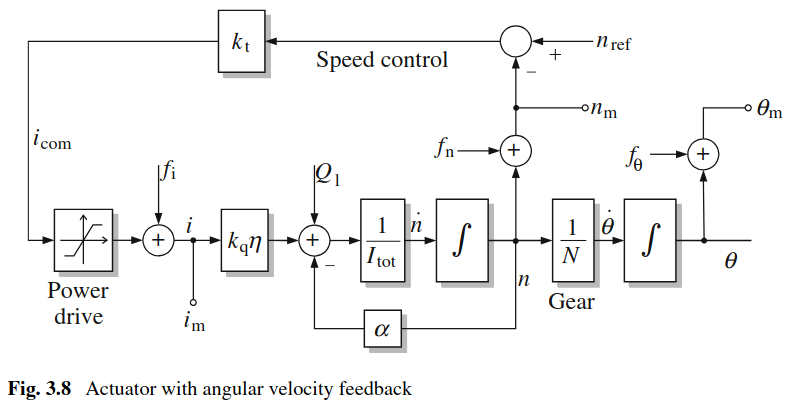

syms n_ref k_t i_com f_i k_q eta i_m n_m theta_m alpha I_tot n N n_dot theta_dot f_theta s i

## Exercise 6.1

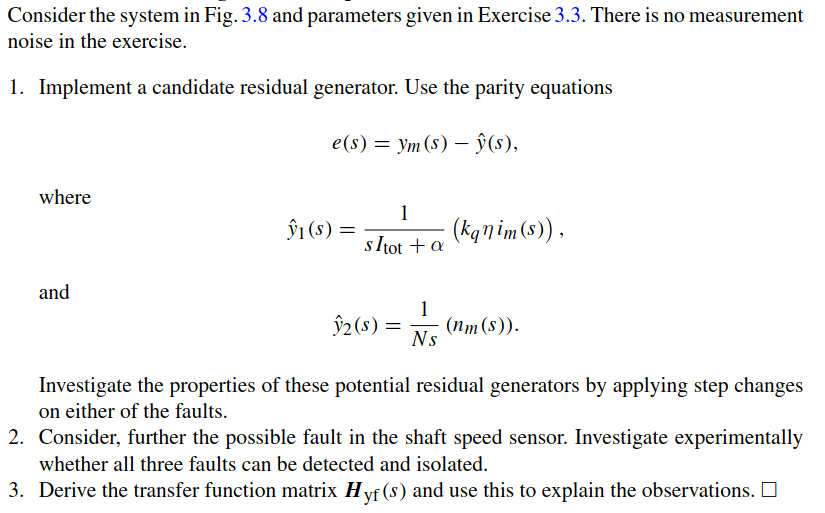

%k_t = 1; i_max = 20; k_q = 0.5; eta = 0.8; N = 100; I_tot = 2*(10^(-3)); alpha = 10^(-4);
%open("Exercise_6_1.slx")

% 6.1.3
A = [-(alpha + k_t*k_q*eta)/I_tot 0
     1/N 0];
B = [k_t*k_q*eta/I_tot
     0];
E_x = [1/I_tot
       0];
F_x = [k_q*eta/I_tot -k_t*k_q*eta/I_tot 0
       0 0 0];
C = [1 0
     0 1
    -k_t 0];
F_y = [0 1 0
       0 0 1
       1 -k_t 0];

H_yf = C * inv(s*eye(rank(C)) - A) * F_x + F_y

$$H\_yf = \begin{array}{l} \left(\begin{array}{ccc} \frac{\eta \,k_{q}}{\sigma_{1}} & 1-\frac{\eta \,k_{q}\,k_{t}}{\sigma_{1}} & 0\\ \frac{\eta \,k_{q}}{N\,s\,\sigma_{1}} & -\frac{\eta \,k_{q}\,k_{t}}{N\,s\,\sigma_{1}} & 1\\ 1-\frac{\eta \,k_{q}\,k_{t}}{\sigma_{1}} & \frac{\eta \,k_{q}\,{k_{t}}^{2}}{\sigma_{1}}-k_{t} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha +I_{\mathrm{tot}}\,s+\eta \,k_{q}\,k_{t} \end{array}$$

## Exercise 6.2

A = [-(alpha)/I_tot 0
    1/N 0];
B = [k_q*eta/I_tot
    0];
C = eye(2);
E_x = [1/I_tot
    0];

### Exercise 6.2.1

H_yu = C * inv(s*eye(2) - A) * B

$$H\_yu = \left(\begin{array}{c} \frac{\eta \,k_{q}}{\alpha +I_{\mathrm{tot}}\,s}\\ \frac{\eta \,k_{q}}{N\,s\,\left(\alpha +I_{\mathrm{tot}}\,s\right)} \end{array}\right)$$

H_yd = C * inv(s*eye(rank(C)) - A) * E_x

$$H\_yd = \left(\begin{array}{c} \frac{1}{\alpha +I_{\mathrm{tot}}\,s}\\ \frac{1}{N\,s\,\left(\alpha +I_{\mathrm{tot}}\,s\right)} \end{array}\right)$$

### Exercise 6.2.2

H = [H_yu H_yd
    eye(rank(H_yu)) zeros(rank(H_yu))]

$$H = \left(\begin{array}{cc} \frac{\eta \,k_{q}}{\alpha +I_{\mathrm{tot}}\,s} & \frac{1}{\alpha +I_{\mathrm{tot}}\,s}\\ \frac{\eta \,k_{q}}{N\,s\,\left(\alpha +I_{\mathrm{tot}}\,s\right)} & \frac{1}{N\,s\,\left(\alpha +I_{\mathrm{tot}}\,s\right)}\\ 1 & 0 \end{array}\right)$$